load("sham_PSTH.mat")

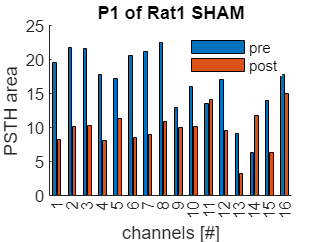

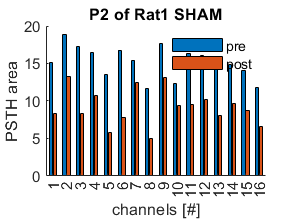

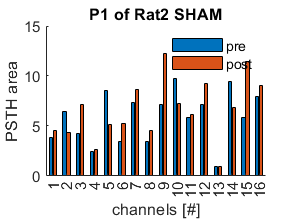

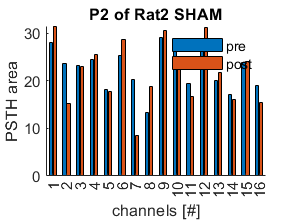

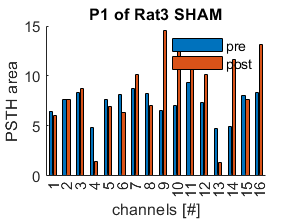

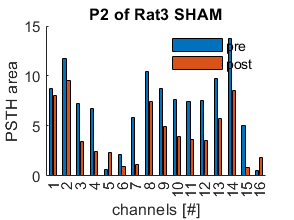

diff_perc=[];
area_pre=zeros(16,6);
area_post=zeros(16,6);
for column=1:6
        figure
        X=(0:length(sham_PSTH{1,1}(1,:))-1)*0.004;

        Int_pre=[];
        Int_post=[];

        for i=1:16
            Int_pre(end+1) = trapz(X, sham_PSTH{1,column}(i,:));
            Int_post(end+1) = trapz(X, sham_PSTH{2,column}(i,:));
        end
              
        bar([Int_pre' Int_post'])

        area_pre(:,column)=Int_pre';
        area_post(:,column)=Int_post';

        diff_perc=[diff_perc; ((Int_post-Int_pre)./Int_pre)*100]; %%---> correggi, la prof faceva (post-pre) diviso pre

        if mod(column,2) == 0
            ttl2=sprintf('P2');
        else
            ttl2=sprintf('P1');
        end

        switch column
            case 1 
                ttl3=sprintf('Rat1');
            case 2
                ttl3=sprintf('Rat1');
            case 3
                ttl3=sprintf('Rat2');
            case 4
                ttl3=sprintf('Rat2');
            case 5
                ttl3=sprintf('Rat3');
            case 6
                ttl3=sprintf('Rat3');
        end

        title(strcat(ttl2,{' of '},ttl3,{' SHAM'}))
        xlabel('channels [#]')
        ylabel('PSTH area')
        xticks(1:16)
        legend('pre', 'post')
        legend boxoff
        box off

end

area_pre_tutti_sham_p1=reshape(area_pre(:,1:2:end),[],1);
save('area_pre_tutti_sham_p1.mat','area_pre_tutti_sham_p1','-v7.3')

area_post_tutti_sham_p1=reshape(area_post(:,1:2:end),[],1);
save('area_post_tutti_sham_p1.mat','area_post_tutti_sham_p1','-v7.3')

area_pre_tutti_sham_p2=reshape(area_pre(:,2:2:end),[],1);
save('area_pre_tutti_sham_p2.mat','area_pre_tutti_sham_p2','-v7.3')

area_post_tutti_sham_p2=reshape(area_post(:,2:2:end),[],1);
save('area_post_tutti_sham_p2.mat','area_post_tutti_sham_p2','-v7.3')

h =   Histogram with properties:

             Data: [-58.0535 -53.2240 -52.4779 -54.4304 -33.9595 -58.5248 -57.8309 -51.5721 -22.9634 -36.0750 4.3692 -43.9179 -63.2727 83.9844 -53.8186 -15.3774]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0.0625 0.5000 0.0625 0.1250 0.0625 0.0625 0 0.0625 0 0 0 0 0 0 0 0.0625 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


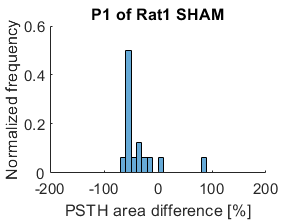

h =   Histogram with properties:

             Data: [-45.1844 -29.4923 -51.4037 -34.9746 -57.3720 -53.8232 -19.7411 -56.7815 -25.5682 -24.3079 -41.5046 -36.1082 -46.9176 -34.7339 -38.2022 -43.9665]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.2500 0.2500 0.2500 0.1875 0.0625 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


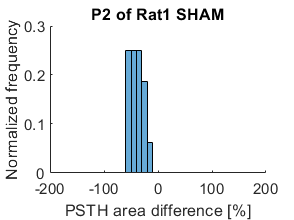

h =   Histogram with properties:

             Data: [17.4273 -32.3462 65.9639 9.0071 -40.4456 52.9536 18.2491 31.2250 71.8259 -26.2191 4.8296 29.9031 2.9321 -27.1907 95.6078 13.2142]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.0625 0.0625 0.1250 0 0 0.1875 0.1875 0.0625 0.0625 0 0.0625 0.0625 0.0625 0 0.0625 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


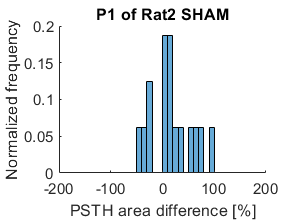

h =   Histogram with properties:

             Data: [12.5054 -35.8013 -0.9381 4.4190 -2.5106 12.8983 -57.7650 39.8436 4.9442 -6.1261 -14.6481 8.3070 8.4916 -5.5281 0.7119 -18.5433]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.0625 0 0.0625 0 0.1250 0.2500 0.3125 0.1250 0 0.0625 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


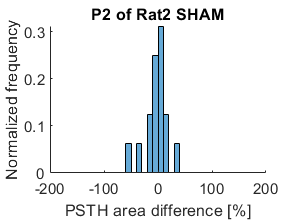

h =   Histogram with properties:

             Data: [-6.8123 -0.6529 5.0050 -69.2708 -8.9034 -22.2108 16.0305 -14.1260 121.9388 81.2279 21.1091 37.5283 -70.8995 133.9465 -5.4865 57.6730]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0 0.0625 0.0625 0 0 0 0.0625 0.0625 0.2500 0.0625 0.0625 0.0625 0.0625 0 0.0625 0 0 0.0625 0 0 0 0.0625 0.0625 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all prop

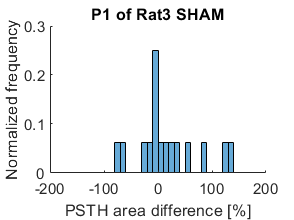

h =   Histogram with properties:

             Data: [-8.5714 -18.7900 -51.7878 -62.9950 269.4309 -56.2992 -80.1517 -28.7530 -43.5361 -48.3060 -50.9451 -52.6432 -40.9052 -38.0895 -84.0000 228.7879]
           Values: [0 0 0 0 0 0 0 0 0 0 0 0.1250 0 0.0625 0.2500 0.1875 0.0625 0.0625 0.0625 0.0625 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 40
         BinEdges: [-200 -190 -180 -170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]
         BinWidth: 10
        BinLimits: [-200 200]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


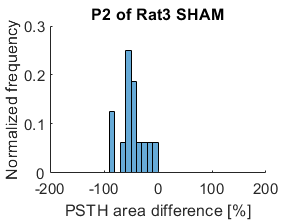

probabilita=[];
for i=1:6
    
    figure
    if mod(i,2) == 0
        ttl2=sprintf('P2');
    else
        ttl2=sprintf('P1');
    end

    switch i
        case 1
            ttl3=sprintf('Rat1');
        case 2
            ttl3=sprintf('Rat1');
        case 3
            ttl3=sprintf('Rat2');
        case 4
            ttl3=sprintf('Rat2');
        case 5
            ttl3=sprintf('Rat3');
        case 6
            ttl3=sprintf('Rat3');
    end

    h=histogram(diff_perc(i,:),'Normalization','probability','BinWidth',10,'BinLimits',[-200 200])
    probabilita=[probabilita;h.Values];

    xlim([-200 200])
    title(strcat(ttl2,{' of '},ttl3,{' SHAM'}))
    xlabel('PSTH area difference [%]')
    ylabel('Normalized frequency')
    box off
end

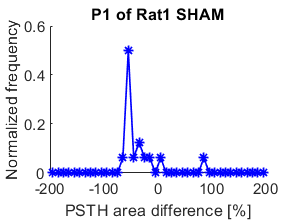

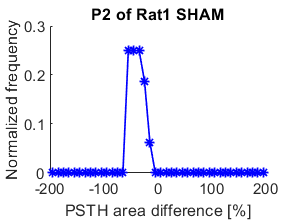

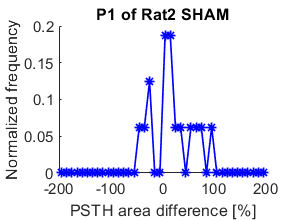

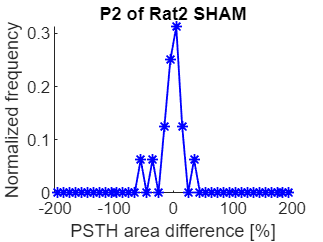

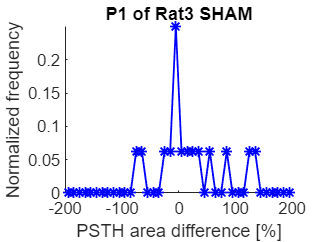

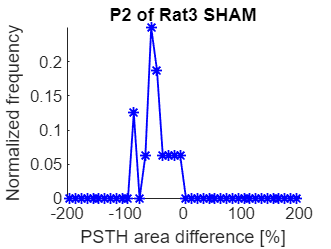

% plot istogrammi linee
x_axis=linspace(-200+10/2,200-10/2,40);
for i=1:6
    
    figure
    if mod(i,2) == 0
        ttl2=sprintf('P2');
    else
        ttl2=sprintf('P1');
    end

    switch i
        case 1
            ttl3=sprintf('Rat1');
        case 2
            ttl3=sprintf('Rat1');
        case 3
            ttl3=sprintf('Rat2');
        case 4
            ttl3=sprintf('Rat2');
        case 5
            ttl3=sprintf('Rat3');
        case 6
            ttl3=sprintf('Rat3');
    end

    plot(x_axis,probabilita(i,:),'*','color','b',LineStyle='-',LineWidth=1)
    

    xlim([-200 200])
    title(strcat(ttl2,{' of '},ttl3,{' SHAM'}))
    xlabel('PSTH area difference [%]')
    ylabel('Normalized frequency')
    box off
end

all_rats_sham_P1=reshape(diff_perc(1:2:end,:),[],1);
save('all_rats_sham_P1.mat','all_rats_sham_P1','-v7.3')

all_rats_sham_P2=reshape(diff_perc(2:2:end,:),[],1);
save('all_rats_sham_P2.mat','all_rats_sham_P2','-v7.3')